clc;
clear;
close all;

% Load dataset 
data = readtable('5G_Handover_Optimization_Dataset.csv');
disp('Dataset loaded successfully');

Dataset loaded successfully


head(data)

    Event_ID    UE_ID    Session_ID    UE_Speed_kmph    UE_Direction_deg    Distance_to_Cell_Edge_m    Serving_RSRP_dBm    Neighbor_RSRP_dBm    Serving_SINR_dB    Neighbor_SINR_dB    Serving_Cell_Load_pct    Neighbor_Cell_Load_pct    PRB_Utilization_pct    Active_Users_Serving    Handover_Count_Last_30s    PingPong_Last_60s    Latency_ms    Packet_Loss_pct    Throughput_Mbps    HO_Hysteresis_dB    Time_to_Trigger_ms    Event_A3_Offset_dB    HO_Decision    HO_Success    PingPong_Event    Session_Drop    QoE_Score
    ________

Data Cleaning & Preprocessing

% Labels (correct column)
labels = categorical(data.HO_Success);
% Features (correct column names)
featureCols = {
    'Serving_RSRP_dBm', ...
    'Neighbor_RSRP_dBm', ...
    'Serving_SINR_dB', ...
    'Serving_Cell_Load_pct', ...
    'UE_Speed_kmph', ...
    'HO_Hysteresis_dB', ...
    'Time_to_Trigger_ms'
};
X = data(:, featureCols);
X = normalize(table2array(X));
y = labels;
% Train-test split
cv = cvpartition(y, 'HoldOut', 0.3);
Xtrain = X(training(cv), :);
ytrain = y(training(cv));
Xtest  = X(test(cv), :);
ytest  = y(test(cv));

Exploratory Data Analysis

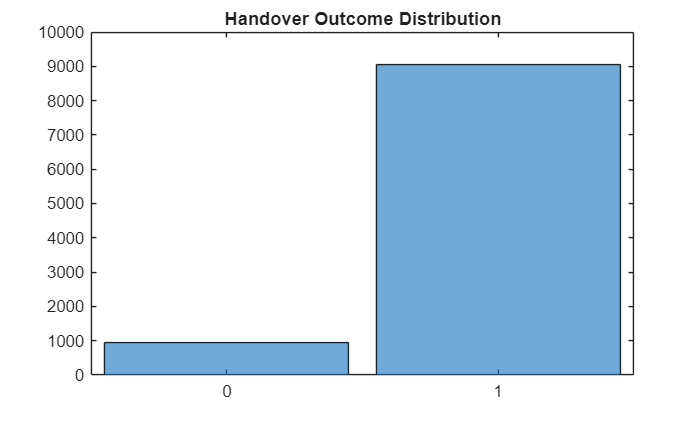

histogram(y)  %Distribution of outcomes
title('Handover Outcome Distribution')    

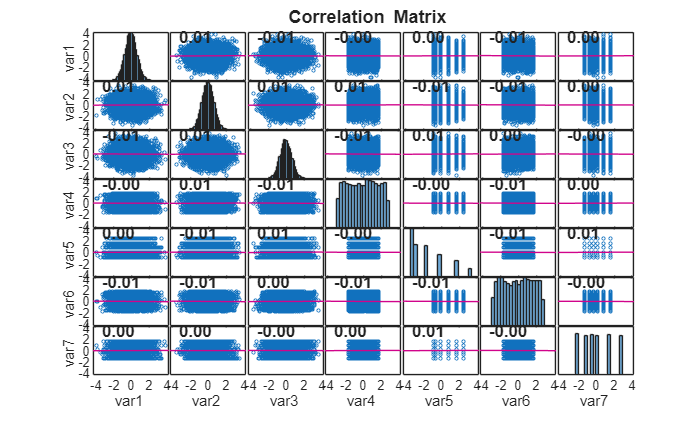

corrplot(X)    %Correlation analysis

Baseline ML Model

rfModel = fitcensemble(Xtrain, ytrain, 'Method','Bag'); %Train Random Forest Classifier
disp('Baseline ML model trained');

Baseline ML model trained


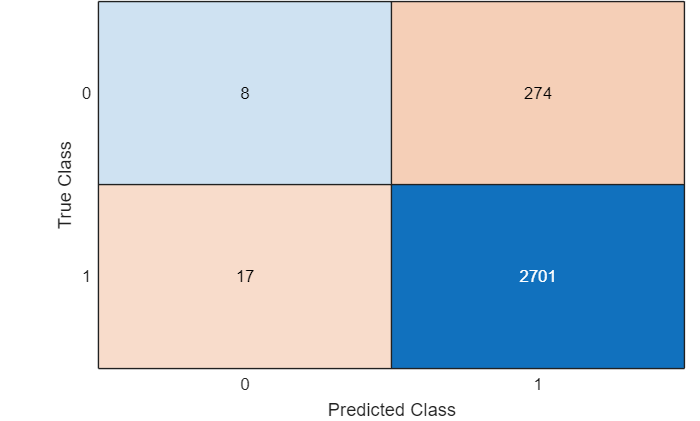


%Confusion Matrix
ypred = predict(rfModel, Xtest);
figure;
confusionchart(ytest, ypred);
title('Confusion Matrix – Baseline ML Model');

accuracy = mean(ypred == ytest);
disp(['Baseline Accuracy: ', num2str(accuracy)]);

Baseline Accuracy: 0.903


Correlation Heatmap 

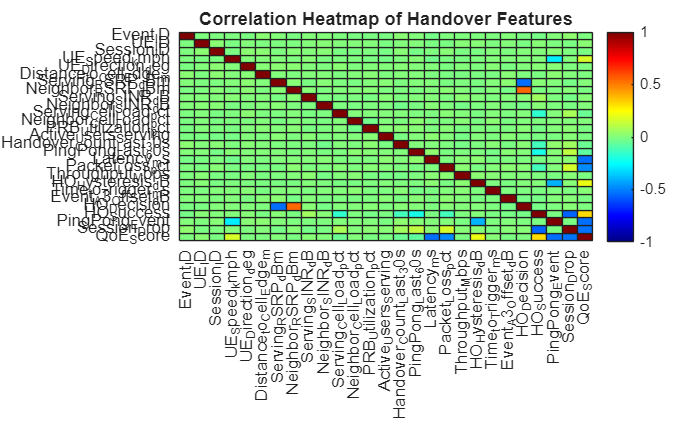

numericData = data(:, vartype('numeric'));
corrMatrix = corr(table2array(numericData));
figure;
heatmap(numericData.Properties.VariableNames, ...
        numericData.Properties.VariableNames, ...
        corrMatrix, ...
        'Colormap', jet, ...
        'ColorLimits', [-1 1]);
title('Correlation Heatmap of Handover Features');

Define State & Action Spaces

obsInfo = rlNumericSpec([5 1]);
obsInfo.Name = 'NetworkState';             %State Space
actInfo = rlFiniteSetSpec([-1 0 1]);
actInfo.Name = 'HysteresisAdjustment';     %Action space

Create RL Environment

env = rlFunctionEnv(obsInfo, actInfo, ...
    @(action,log) stepFunction(action,log), ...
    @() resetFunction(data));

Deep - Q Network

agentOpts = rlDQNAgentOptions( ...
    'UseDoubleDQN', true, ...
    'DiscountFactor', 0.99, ...
    'MiniBatchSize', 64);
agent = rlDQNAgent(obsInfo, actInfo, agentOpts);
disp('RL agent created');

RL agent created


Train RL Agent

trainOpts = rlTrainingOptions( ...
    'MaxEpisodes', 300, ...
    'MaxStepsPerEpisode', height(data), ...
    'Verbose', true, ...
    'Plots','training-progress');

trainingStats = train(agent, env, trainOpts);

Episode:   1/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 10000 | Episode Q0:     8.35
Episode:   2/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 20000 | Episode Q0:    13.93
Episode:   3/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 30000 | Episode Q0:    12.15
Episode:   4/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 40000 | Episode Q0:    10.72
Episode:   5/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 50000 | Episode Q0:    12.18
Episode:   6/300 | Episode reward: 88095.57 | Episode steps: 10000 | Average reward: 88095.57 | Step Count: 60000 | Episode Q0:    12.99


Evaluate RL-Driven Handover

simOpts = rlSimulationOptions('MaxSteps', height(data));
experience = sim(env, agent, simOpts);

totalReward = sum(experience.Reward);
disp(['Total RL Reward: ', num2str(totalReward)]);

Total RL Reward: 88095.5695


Compare Baseline vs RL

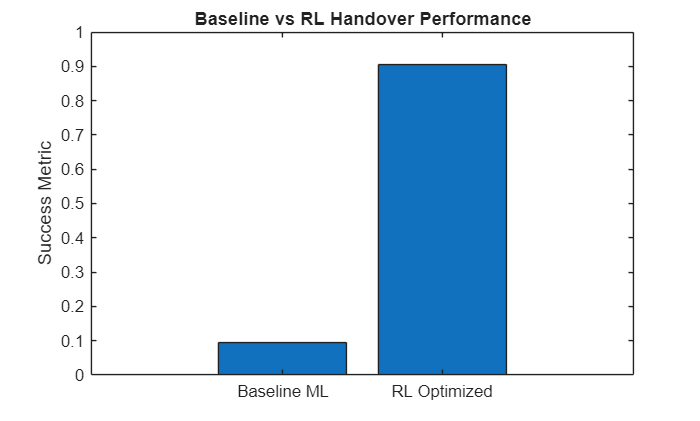

% Baseline ML success rate
baselineSuccess = mean(double(ytest) == 1);

% RL success metric (positive reward steps)
rlRewards = experience.Reward.Data;
rlSuccess = mean(rlRewards > 0);

% Plot comparison
figure;
bar([baselineSuccess, rlSuccess]);
set(gca,'XTickLabel',{'Baseline ML','RL Optimized'});
ylabel('Success Metric');
title('Baseline vs RL Handover Performance');

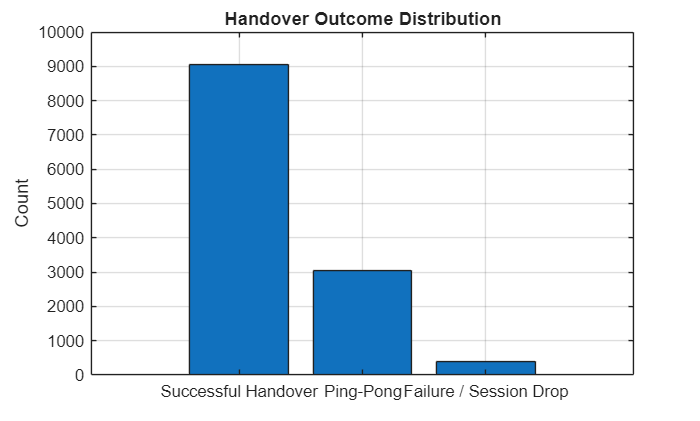

% ---- Handover Outcome Distribution ----

successCount  = sum(data.HO_Success == 1);
pingpongCount = sum(data.PingPong_Event == 1);
failureCount  = sum(data.Session_Drop == 1);

counts = [successCount, pingpongCount, failureCount];

figure;
bar(counts);
set(gca, 'XTickLabel', ...
    {'Successful Handover', 'Ping-Pong', 'Failure / Session Drop'});
ylabel('Count');
title('Handover Outcome Distribution');
grid on;